clc;
clear all;
close all;

syms phi theta;
X= 0:5:50

X =      0     5    10    15    20    25    30    35    40    45    50


Y= [0.99,1,0.95,0.9,0.8,0.6,0.5,0.3,0.2,0.1, 0.05]%relative intensity values taken from radiation pattern on datasheet of XST-3535-UV-A60-CE280-01

Y =     0.9900    1.0000    0.9500    0.9000    0.8000    0.6000    0.5000    0.3000    0.2000    0.1000    0.0500


%I_func=1-(phi/45)^2
I_func=-0.5*sind(3.3*(phi-30))+0.5

$$I\_func = \frac{1}{2}-\frac{\sin\left(\frac{\pi \,\left(\frac{33\,\varphi }{10}-99\right)}{180}\right)}{2}$$

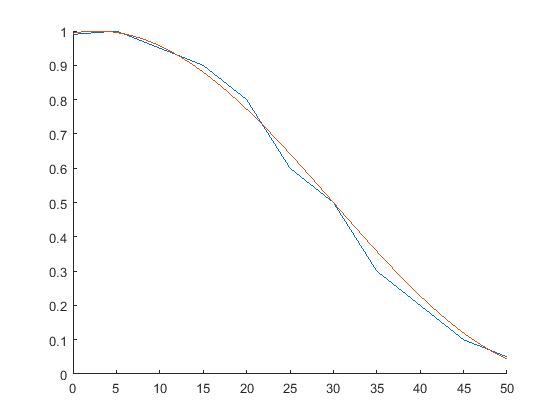

hold on;
plot(X,Y)
fplot(I_func)
xlim([0 50])
ylim([0 1])


%overall power is intensity integrated over the sphere surface
%power is only relative here because relative intensities were used.
W_emit=int(int(I_func*sind(phi),phi,0,45),theta,0,360);
W_capture=int(int(I_func*sind(phi),phi,0,26.5),theta,0,360);
relative_power_A=eval(W_capture/W_emit)

relative_power_A = 0.5796




%For Setup B:
W_emit=int(int(I_func*sind(phi),phi,0,45),theta,0,360);
W_capture=int(int(I_func*sind(phi),phi,22-3.3,22+3.3),theta,0,6.6);
relative_power_B=eval(W_capture/W_emit)

relative_power_B = 0.0039